# 实验三

## 典型离散信号傅里叶变换

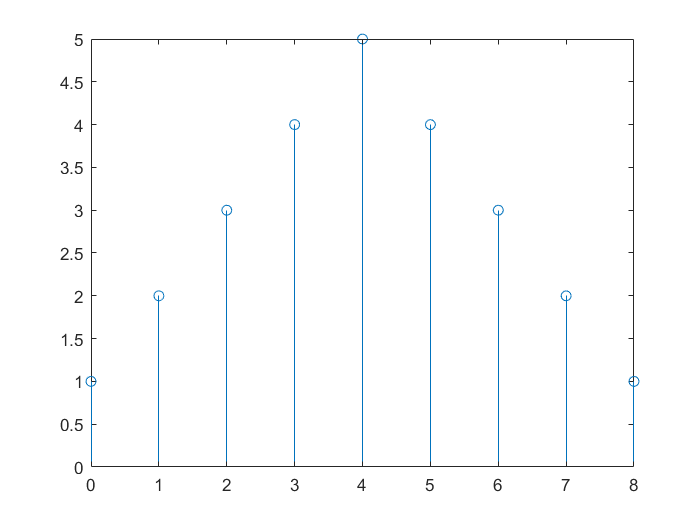

N = 10000;
Fs = 1000;
x1 = triangle_wave(0:N-1);
x2 = sqaure_wave(0:N-1);
X1 = fft(x1);
X2 = fft(x2);
x1_t = ifft(X1);
figure; stem(0:8, x1(1:9));

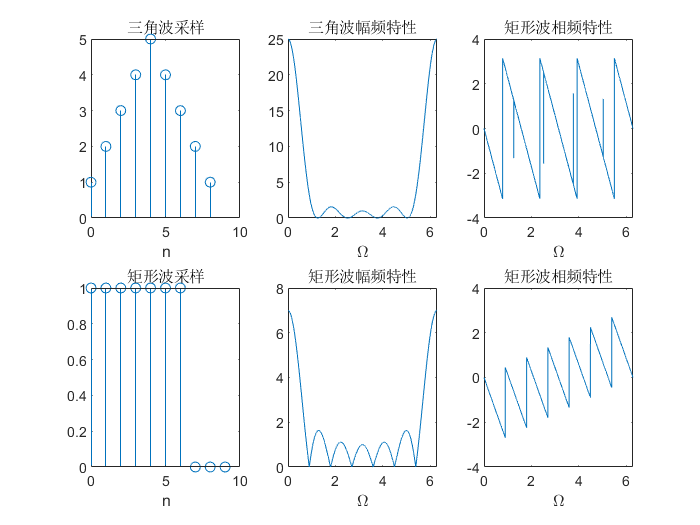

figure;
subplot(2, 3, 1); stem(0:8, x1(1:9)); title("三角波采样"); xlabel("n");
subplot(2, 3, 4); stem(0:9, x2(1:10)); title("矩形波采样"); xlabel("n");
subplot(2, 3, 2); plot(0:(2*0.1*pi/Fs):2*pi-(2*0.1*pi/Fs), abs(X1)); title("三角波幅频特性"); xlabel("\Omega");
subplot(2, 3, 5); plot(0:(2*0.1*pi/Fs):2*pi-(2*0.1*pi/Fs), abs(X2)); title("矩形波幅频特性"); xlabel("\Omega");
subplot(2, 3, 3); plot(0:(2*0.1*pi/Fs):2*pi-(2*0.1*pi/Fs), angle(X1)); title("矩形波相频特性"); xlabel("\Omega");
subplot(2, 3, 6); plot(0:(2*0.1*pi/Fs):2*pi-(2*0.1*pi/Fs), angle(X2)); title("矩形波相频特性"); xlabel("\Omega");

## 离散序列线性卷积

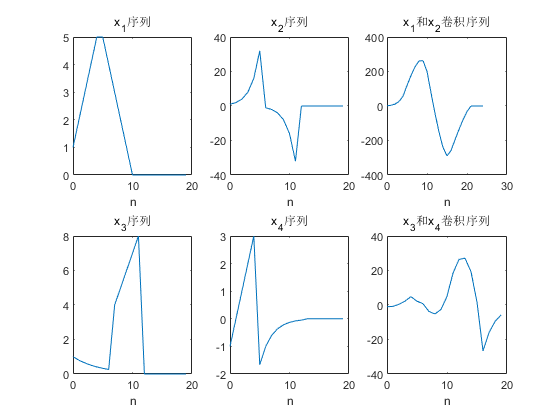

N = 20000;
x1 = signal211(0:N-1);
x2 = signal212(0:N-1);
x3 = signal221(0:N-1);
x4 = signal222(0:N-1);
X1 = fft(x1);
X2 = fft(x2);
X3 = fft(x3);
X4 = fft(x4);
X12 = X1 .* X2;
X34 = X3 .* X4;
x12 = ifft(X12);
x34 = ifft(X34);
figure;
subplot(2, 3, 1); plot(0:19, x1(1:20)); title("x_1序列"); xlabel("n");
subplot(2, 3, 2); plot(0:19, x2(1:20)); title("x_2序列"); xlabel("n");
subplot(2, 3, 3); plot(0:24, x12(1:25)); title("x_1和x_2卷积序列"); xlabel("n");
subplot(2, 3, 4); plot(0:19, x3(1:20)); title("x_3序列"); xlabel("n");
subplot(2, 3, 5); plot(0:19, x4(1:20)); title("x_4序列"); xlabel("n");
subplot(2, 3, 6); plot(0:19, x34(1:20)); title("x_3和x_4卷积序列"); xlabel("n");

## 滤波

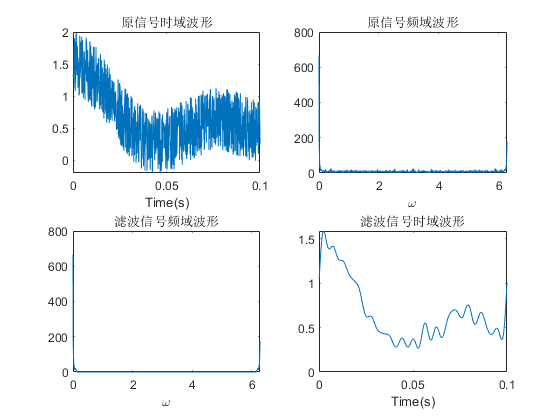

Fs = 10000;
t = (1/Fs):(1/Fs):0.1;
x = signal3(t);
X = fft(x);
Xf = X;
Xf(20:end-20) = 0;  % low pass filter
xf = ifft(Xf);
figure;
subplot(2, 2, 1); plot(t, x); title("原信号时域波形"); xlabel("Time(s)");
subplot(2, 2, 2); plot(0:(2*pi/(0.1*Fs)):2*pi-(2*pi/(0.1*Fs)), abs(X)); title("原信号频域波形"); xlabel("\Omega");
subplot(2, 2, 3); plot(0:(2*pi/(0.1*Fs)):2*pi-(2*pi/(0.1*Fs)), abs(Xf)); title("滤波信号频域波形"); xlabel("\Omega");
subplot(2, 2, 4); plot(t, abs(xf)); title("滤波信号时域波形"); xlabel("Time(s)");

## 采样频率变化

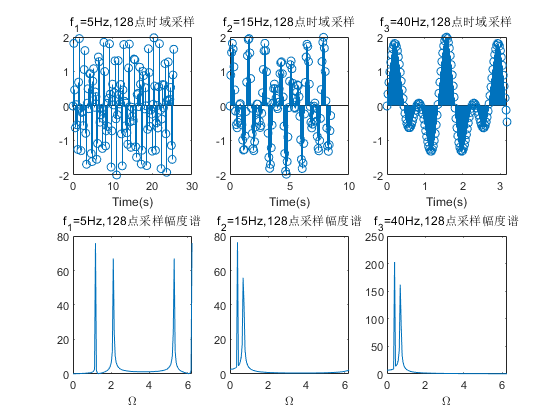

f11 = 5;
f12 = 15;
f13 = 40;
t11 = 0:(1/f11):30;
t12 = 0:(1/f12):10;
t13 = 0:(1/f13):10;
x11 = signal4(t11);
x12 = signal4(t12);
x13 = signal4(t13);
x11_128 = x11(1:128);
x12_128 = x12(1:128);
x13_128 = x13(1:128);
X11 = fft(x11);
X12 = fft(x12);
X13 = fft(x13);
figure;
subplot(2, 3, 1); stem(0:(1/f11):(127/f11), x11(1:128)); title("f_1=5Hz,128点时域采样"); xlabel("Time(s)");
subplot(2, 3, 2); stem(0:(1/f12):(127/f12), x12(1:128)); title("f_2=15Hz,128点时域采样"); xlabel("Time(s)");
subplot(2, 3, 3); stem(0:(1/f13):(127/f13), x13(1:128)); title("f_3=40Hz,128点时域采样"); xlabel("Time(s)");
subplot(2, 3, 4); plot(0:(2*pi/(128)):2*pi-(2*pi/(128)), abs(X11(1:128))); title("f_1=5Hz,128点采样幅度谱"); xlabel("\Omega");
subplot(2, 3, 5); plot(0:(2*pi/(128)):2*pi-(2*pi/(128)), abs(X12(1:128))); title("f_2=15Hz,128点采样幅度谱"); xlabel("\Omega");
subplot(2, 3, 6); plot(0:(2*pi/(128)):2*pi-(2*pi/(128)), abs(X13(1:128))); title("f_3=40Hz,128点采样幅度谱"); xlabel("\Omega");

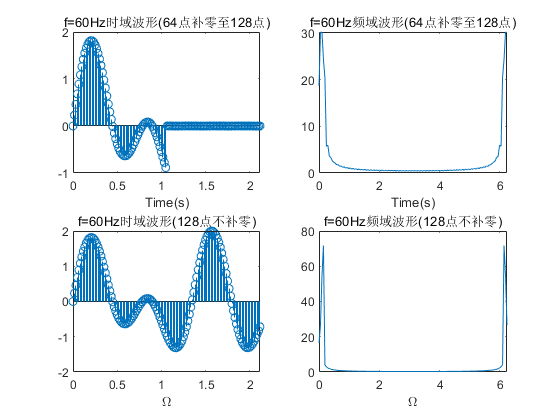


f2 = 60;
t2 = 0:(1/f2):20;
x2 = signal4(t2);
x2p = [x2(1:64), zeros([1, 64])];
X2 = fft(x2p);
figure;
subplot(2, 2, 1); stem(0:(1/f2):(127/f2), x2p); title("f=60Hz时域波形(64点补零至128点)"); xlabel("Time(s)");
subplot(2, 2, 2); plot(0:(2*pi/(128)):2*pi-(2*pi/(128)), abs(X2)); title("f=60Hz频域波形(64点补零至128点)"); xlabel("Time(s)");

f3 = 60;
t3 = 0:(1/f2):20;
x3 = signal4(t2);
x3p = x3(1:128);
X3 = fft(x3p);
subplot(2, 2, 3); stem(0:(1/f3):(127/f3), x3p); title("f=60Hz时域波形(128点不补零)"); xlabel("\Omega");
subplot(2, 2, 4); plot(0:(2*pi/(128)):2*pi-(2*pi/(128)), abs(X3)); title("f=60Hz频域波形(128点不补零)"); xlabel("\Omega");

## 趣味小实验

Fs = 8000;
t = 0:(1/Fs):17;
tiger_ori = zeros([1, 16*Fs*0.5]);
f = [261.63, 293.66, 329.63, 261.63, 261.63, 293.63, 329.63, 261.63, 329.63, 349.23, 392, 392, 329.63, 349.23, 392, 392];
for i = 1:16
    tiger_ori((i-1)*Fs*0.5+1:i*Fs*0.5) = sin(2*pi*f(i)*t((i-1)*Fs*0.5+1:i*Fs*0.5));
end
Tiger_ori = fft(tiger_ori);
figure;
subplot(1, 3, 1); plot(linspace(0, 6.28, length(Tiger_ori)), abs(Tiger_ori)); title("原音乐频域"); xlabel("\Omega");
audiowrite('5-3.wav',tiger_ori,Fs);

Tiger_filter = Tiger_ori;
Tiger_filter(0.5e4:5.5e4) = 0;
tiger_filter = ifft(Tiger_filter);
subplot(1, 3, 2); plot(linspace(0, 6.28, length(Tiger_filter)), abs(Tiger_filter));  title("消除高频分量后频域"); xlabel("\Omega");
audiowrite('5-4.wav',abs(tiger_filter),Fs);

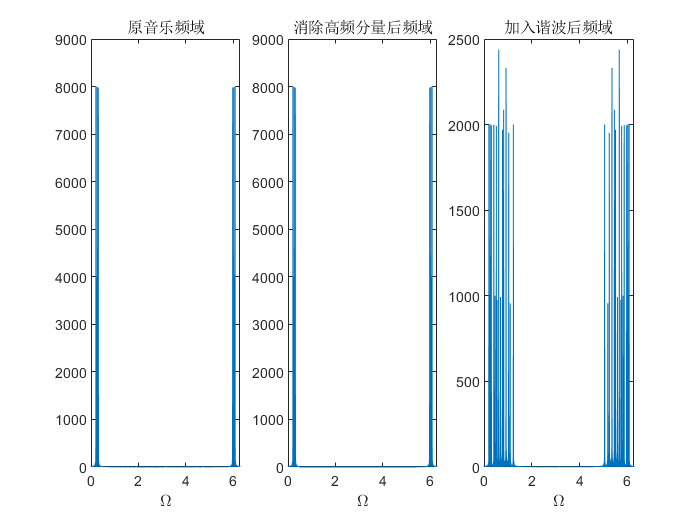


tiger_high = tiger_ori;
for i = 1:16
    tiger_high((i-1)*Fs*0.5+1:i*Fs*0.5) = 0.25 * (sin(2*pi*f(i)*t((i-1)*Fs*0.5+1:i*Fs*0.5)) + ...
        sin(4*pi*f(i)*t((i-1)*Fs*0.5+1:i*Fs*0.5)) + ...
        sin(6*pi*f(i)*t((i-1)*Fs*0.5+1:i*Fs*0.5)) + ...
        sin(8*pi*f(i)*t((i-1)*Fs*0.5+1:i*Fs*0.5)));
end
Tiger_high = fft(tiger_high);
subplot(1, 3, 3); plot(linspace(0, 6.28, length(Tiger_high)), abs(Tiger_high));  title("加入谐波后频域"); xlabel("\Omega");

audiowrite('5-5.wav',abs(tiger_high),Fs);